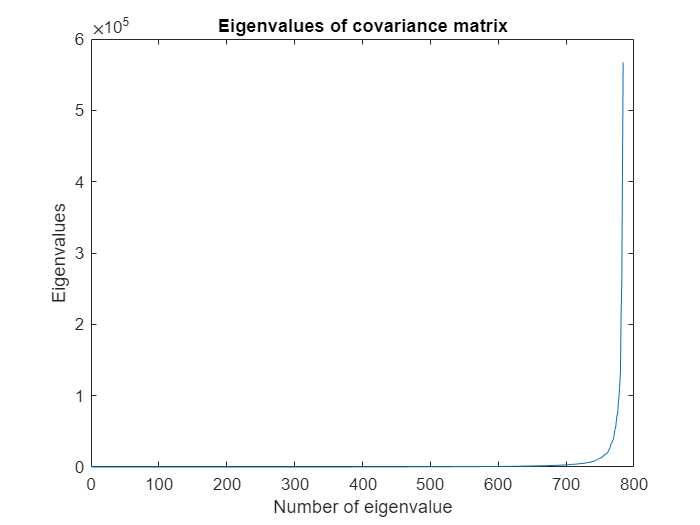

%Loading the dataset
load('../../data/mnist.mat');
axis equal
count = 0;
digits= zeros(28,28,1); %Matrix to store the data for each digit
for i=1:60000
    if labels_train(i) == 0 %For the digit 0
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); %Casting to make the integers into floating point 
data_matrix = reshape(digits,28*28,count); %Reshaping to get a 784x1 coulumn vector for each image
mean_vector = sum(data_matrix,2)/count; %Calculating the mean vector
mean_matrix = ones(28*28,count); %Mean matrix i.e. each column is the mean vector
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1); %Calculating the covariance matrix
[V,D] = eig(cov_matrix); %Calculating the eigenvectors and eigenvalues
[d,ind1] = sort(abs(diag(D))); %Getting the eigenvalues in sorted order(Ascending)
plot(d,'-') %Plotting the sorted eigen values
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'

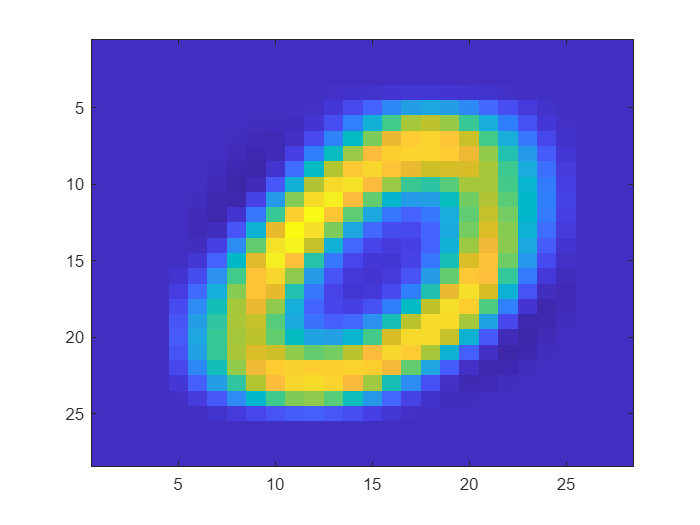

[d,ind] = sort(abs(diag(D)),'descend'); %Getting the eigenvalues in descending order
principle_eigenval= d(1,1); %Finding the principle eigenvalue
principle_eigenvector = V(:,ind(1,1)); %Finding the principle eigenvector
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); %Displaying the mean minus principle mode of variation

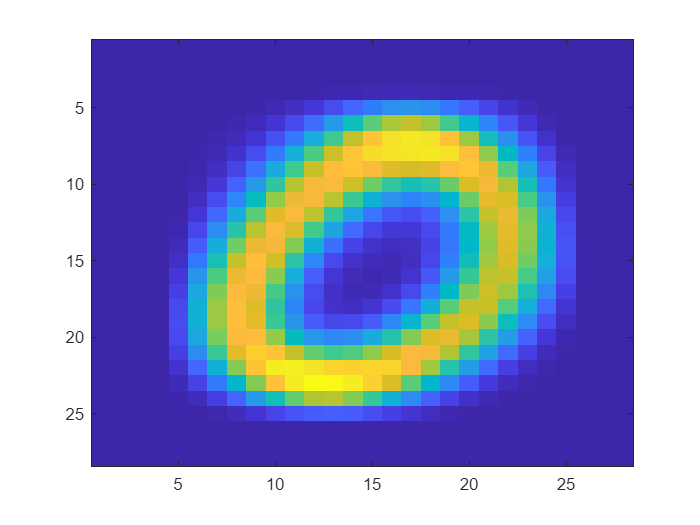

imagesc(reshape(mean_vector,28,28)); %Displaying the mean

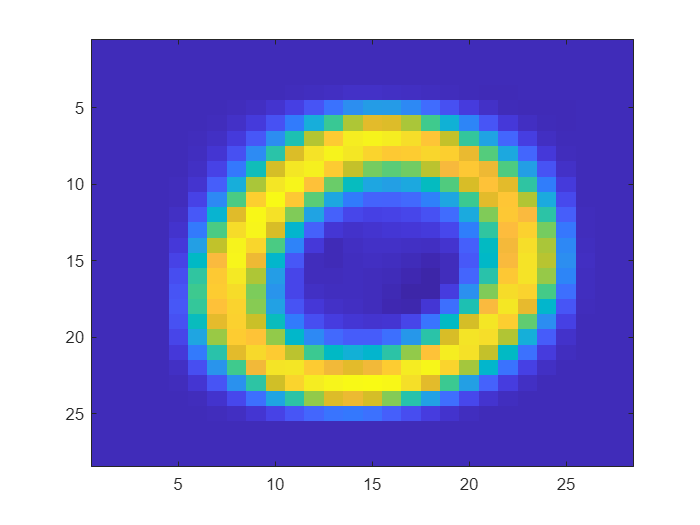

imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); %Displaying the mean plus principle mode of variation

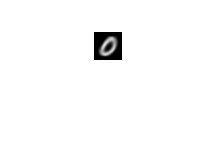

imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28))); %Displaying the mean minus principle mode of variation greyscale

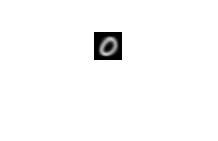

imshow(uint8(reshape(mean_vector,28,28))); %Displaying the mean greyscale

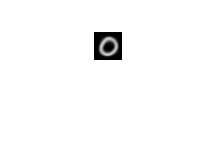

imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28))); %Displaying the mean plus principle mode of variation greyscale

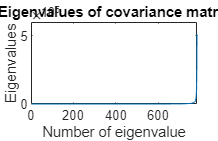


%Doing the same for other digits:

%For the digit 1:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 1
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'

[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 2:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 2
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 3:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 3
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 4:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 4
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 5:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 5
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 6:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 6
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 7:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 7
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 8:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 8
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));

%For the digit 9:
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 9
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); 
data_matrix = reshape(digits,28*28,count); 
mean_vector = sum(data_matrix,2)/count; 
mean_matrix = ones(28*28,count); 
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix).')/(count-1);
[V,D] = eig(cov_matrix);
[d,ind1] = sort(abs(diag(D))); 
plot(d,'-') 
title 'Eigenvalues of covariance matrix'
ylabel 'Eigenvalues'
xlabel 'Number of eigenvalue'
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1); 
principle_eigenvector = V(:,ind(1,1));
imagesc(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imagesc(reshape(mean_vector,28,28)); 
imagesc(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)); 
imshow(uint8(reshape(mean_vector,28,28)-reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));
imshow(uint8(reshape(mean_vector,28,28)));
imshow(uint8(reshape(mean_vector,28,28)+reshape(principle_eigenvector*sqrt(principle_eigenval),28,28)));